# DMD Tweezers

DMD beam parameters

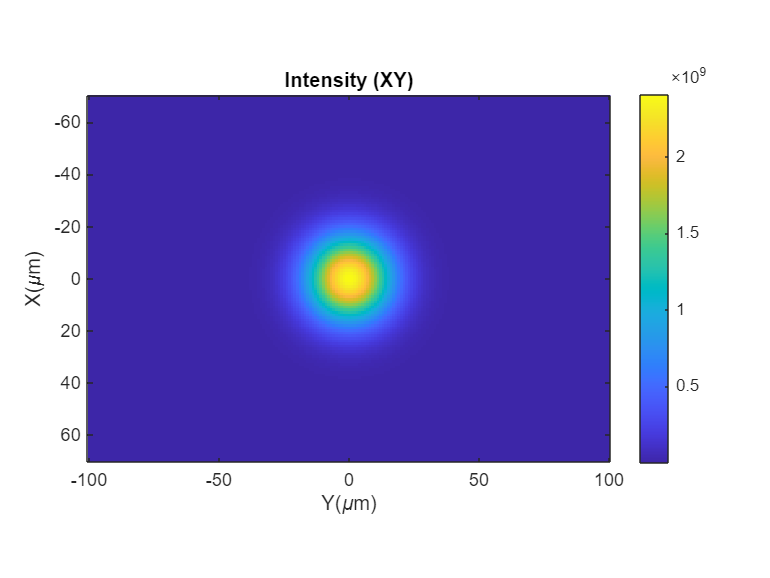

clear
clc

DMDBeam.Power = 2000;
DMDBeam.Pol = [0, 0];
DMDBeam.Wave = 0.532;
DMDBeam.Ang = [0, 0];
DMDBeam.Waist = [23,23];
DMDBeam.Phase = 0;

XRange = -70:70;
YRange = -100:100;
ZRange = -20:0.1:20;

XSize = length(XRange);
YSize = length(YRange);
ZSize = length(ZRange);

[Y,X,Z] = meshgrid(YRange,XRange,0);
[IXY,~,Pol] = gaussianFull(DMDBeam,[X(:),Y(:),Z(:)]);
imagesc(YRange,XRange,reshape(IXY,XSize,YSize))
colorbar
daspect([1 1 1])
xlabel('Y(\mum)')
ylabel('X(\mum)')
title('Intensity (XY)')

Potential depth

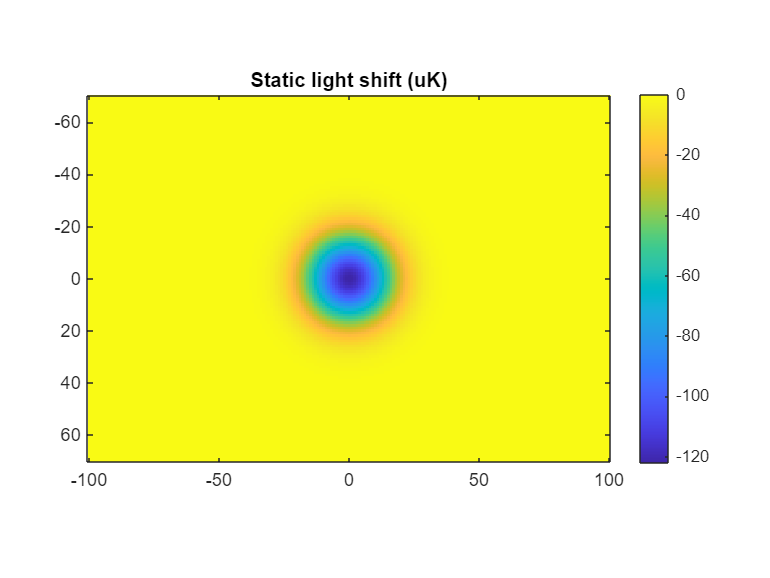

PotentialStatic = aNLJ('s',6,0,1/2,DMDBeam.Wave,'ExpuK')*reshape(IXY,XSize,YSize);
imagesc(YRange,XRange,PotentialStatic)
colorbar
daspect([1 1 1])
title('Static light shift (uK)')